clc, clear;     %ctrl + enter to compile
syms s lambda D   %syms defines symbols
t1 = 4.9741e-06;
t2 = 5.7877e-06;
theta = 1.559e-05;
K = 12.325; 
G = (K * D)/((t1*s + 1)*(t2*s + 1))     %D = exp(-theta*s) to represent delay

$$G = \frac{493\,\text{D}}{40\,\left(\frac{6832910123226161\,s}{1180591620717411303424}+1\right)\,\left(\frac{1468095195152619\,s}{295147905179352825856}+1\right)}$$

F = 1/(1 + lambda*s)   %filter constant

$$F = \frac{1}{\lambda \,s+1}$$

C_IMC = F * D / G 

$$C\_IMC = \frac{40\,\left(\frac{6832910123226161\,s}{1180591620717411303424}+1\right)\,\left(\frac{1468095195152619\,s}{295147905179352825856}+1\right)}{493\,\left(\lambda \,s+1\right)}$$

C = C_IMC/(1 - C_IMC*G)

$$C = -\frac{40\,\left(\frac{6832910123226161\,s}{1180591620717411303424}+1\right)\,\left(\frac{1468095195152619\,s}{295147905179352825856}+1\right)}{493\,\left(\frac{\text{D}}{\lambda \,s+1}-1\right)\,\left(\lambda \,s+1\right)}$$

C = subs(C, D, 1-theta*s)   %subs substitutes the value 

$$C = \frac{40\,\left(\frac{6832910123226161\,s}{1180591620717411303424}+1\right)\,\left(\frac{1468095195152619\,s}{295147905179352825856}+1\right)}{493\,\left(\frac{\frac{4601355841746111\,s}{295147905179352825856}-1}{\lambda \,s+1}+1\right)\,\left(\lambda \,s+1\right)}$$

C = expand(C)   %expand command expands all the variables and expands individual terms

$$C = \begin{array}{l} \frac{3736850265834305\,s}{4279644625100615974912\,\sigma_{1}}+\frac{40}{493\,\sigma_{1}}+\frac{50156812604090083862465242328295\,s^{2}}{21473178482178900798392791227374301215719424\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\lambda \,s+\frac{4601355841746111\,s}{295147905179352825856\,\left(\lambda \,s+1\right)}-\frac{1}{\lambda \,s+1}-\frac{\lambda \,s}{\lambda \,s+1}+\frac{4601355841746111\,\lambda \,s^{2}}{295147905179352825856\,\left(\lambda \,s+1\right)}+1 \end{array}$$

C1 = collect(C*s, s)    %colllects mention which variable we want to collect after 

$$C1 = \frac{50156812604090083862465242328295\,s^{2}+18749699974808348498605590990668431360\,s+1742245718635204932932477990050653242654720}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944}$$

                        % rearrangment and shows it in form of second input
                        % to function
coef1 = coeffs(C1, s)   %generates array of corfficients on the basis of the second

$$coef1 = \left(\begin{array}{ccc} \frac{1742245718635204932932477990050653242654720}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944} & \frac{18749699974808348498605590990668431360}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944} & \frac{50156812604090083862465242328295}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944} \end{array}\right)$$

                        %input that is provided

%assigning the coefficients to their respective constants
Kp = coef1(2)  

$$Kp = \frac{18749699974808348498605590990668431360}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944}$$

Ki = coef1(1)

$$Ki = \frac{1742245718635204932932477990050653242654720}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944}$$

Kd = coef1(3)

$$Kd = \frac{50156812604090083862465242328295}{21473178482178900798392791227374301215719424\,\lambda +334766852537169095815540667893042642944}$$

%save command saves the file along with the variables in the same directory
save pidgains.mat Kp Ki Kd 

clc, clear
t1 = 4.9741e-06;
t2 = 5.7877e-06;
theta = 1.559e-05;
K = 12.325; 
s = tf('s'); %used to define the transfer function
G = K * exp(-theta*s)/((t1 * s + 1 )*(t2*s + 1))

G =
 
                                  12.32
  exp(-1.56e-05*s) * -------------------------------
                     2.879e-11 s^2 + 1.076e-05 s + 1
 
Continuous-time transfer function.




%using a for loop for checking response on various values of lambda
for lambda = 0:0.001:0.007

    %load command loads the values that were saved in the directory
    load('pidgains.mat')
    Kp = double(subs(Kp))
    Ki = double(subs(Ki))
    Kd = double(subs(Kd))
    %without using the double command the pid command gives an error
    C = pid(Kp, Ki, Kd)
    %for closed loop transfer function
    T = G * C /(1 + G * C);
    step(T);
    sim("IMCeqv0.slx")

    hold on
end

Kp = 0.0560

Ki = 5.2044e+03

Kd = 1.4983e-07

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.056, Ki = 5.2e+03, Kd = 1.5e-07
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 8.5976e-04

Ki = 79.8904

Kd = 2.2999e-09

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.00086, Ki = 79.9, Kd = 2.3e-09
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 4.3321e-04

Ki = 40.2542

Kd = 1.1589e-09

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000433, Ki = 40.3, Kd = 1.16e-09
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.8955e-04

Ki = 26.9055

Kd = 7.7457e-10

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.00029, Ki = 26.9, Kd = 7.75e-10
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.1744e-04

Ki = 20.2052

Kd = 5.8168e-10

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000217, Ki = 20.2, Kd = 5.82e-10
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.7409e-04

Ki = 16.1767

Kd = 4.6571e-10

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000174, Ki = 16.2, Kd = 4.66e-10
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.4515e-04

Ki = 13.4876

Kd = 3.8829e-10

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000145, Ki = 13.5, Kd = 3.88e-10
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.2446e-04

Ki = 11.5651

Kd = 3.3294e-10

C =
 
             1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.000124, Ki = 11.6, Kd = 3.33e-10
 
Continuous-time PID controller in parallel form.



ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


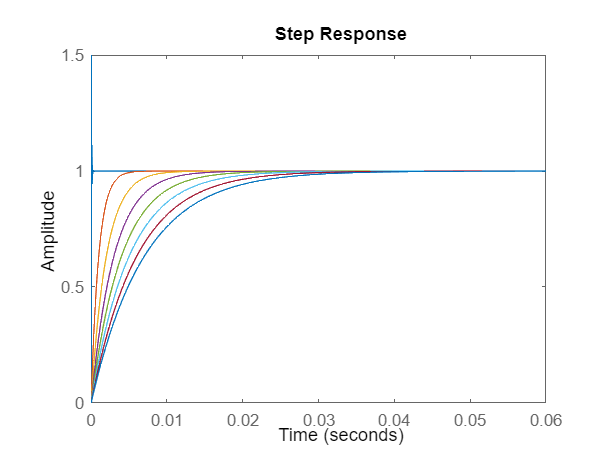

    hold off

%from the graph we can see that the increase of filter constant the
%response time slows down more and more 
%higher value of lambda ensures that the stability of the system is
%increase as well
%response time is imporved => stability reduces 


clc, clear
t1 = 4.9741e-06;
t2 = 5.7877e-06;
theta = 1.559e-05;
K = 12.325; 
s = tf('s'); %used to define the transfer function
G = K * exp(-theta*s)/((t1 * s + 1 )*(t2*s + 1))

G =
 
                                  12.32
  exp(-1.56e-05*s) * -------------------------------
                     2.879e-11 s^2 + 1.076e-05 s + 1
 
Continuous-time transfer function.




%using a for loop for checking response on various values of lambda
for lambda = 0:0.001:0.007
    %load command loads the values that were saved in the directory
    load('pidgains.mat')
    Kp = double(subs(Kp))
    Ki = double(subs(Ki))
    Kd = double(subs(Kd))
    %without using the double xxcommand the pid command gives an error
    %C = pid(Kp, Ki, Kd)
    %for closed loop transfer function
    %T = G * C /(1 + G * C);
    %step(T);

    sim("IMCeqv0.slx")
    controlac = ans.u;
    plot(controlac);
    %holds all the values of previous runs
    hold on
end

Kp = 0.0560

Ki = 5.2044e+03

Kd = 1.4983e-07

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 8.5976e-04

Ki = 79.8904

Kd = 2.2999e-09

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 4.3321e-04

Ki = 40.2542

Kd = 1.1589e-09

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.8955e-04

Ki = 26.9055

Kd = 7.7457e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.1744e-04

Ki = 20.2052

Kd = 5.8168e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.7409e-04

Ki = 16.1767

Kd = 4.6571e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.4515e-04

Ki = 13.4876

Kd = 3.8829e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.2446e-04

Ki = 11.5651

Kd = 3.3294e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


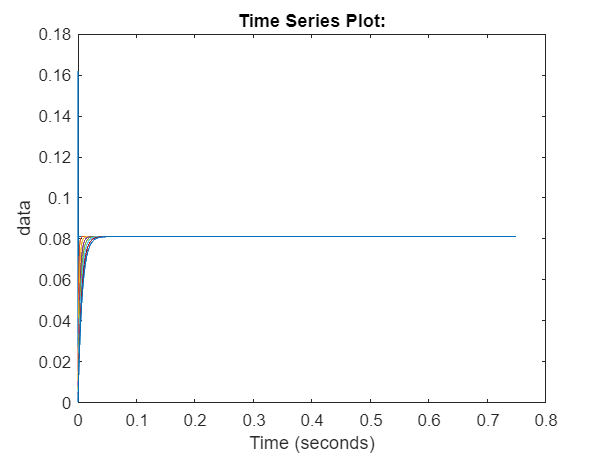

    hold off

clc, clear
t1 = 4.9741e-06;
t2 = 5.7877e-06;
theta = 1.559e-05;
K = 12.325; 
s = tf('s'); %used to define the transfer function
G = K * exp(-theta*s)/((t1 * s + 1 )*(t2*s + 1))

G =
 
                                  12.32
  exp(-1.56e-05*s) * -------------------------------
                     2.879e-11 s^2 + 1.076e-05 s + 1
 
Continuous-time transfer function.




%using a for loop for checking response on various values of lambda
for lambda = 0:0.001:0.007
    %load command loads the values that were saved in the directory
    load('pidgains.mat')
    Kp = double(subs(Kp))
    Ki = double(subs(Ki))
    Kd = double(subs(Kd))
    %without using the double command the pid command gives an error
    %C = pid(Kp, Ki, Kd)
    %for closed loop transfer function
    %T = G * C /(1 + G * C);
    %step(T);

    sim("IMCeqv0.slx")
    errorac = ans.e;
    plot(errorac);
    %holds all the values of previous runs
    hold on
end

Kp = 0.0560

Ki = 5.2044e+03

Kd = 1.4983e-07

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 8.5976e-04

Ki = 79.8904

Kd = 2.2999e-09

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 4.3321e-04

Ki = 40.2542

Kd = 1.1589e-09

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.8955e-04

Ki = 26.9055

Kd = 7.7457e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 2.1744e-04

Ki = 20.2052

Kd = 5.8168e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.7409e-04

Ki = 16.1767

Kd = 4.6571e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.4515e-04

Ki = 13.4876

Kd = 3.8829e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


Kp = 1.2446e-04

Ki = 11.5651

Kd = 3.3294e-10

ans =   Simulink.SimulationOutput:

                      e: [1x1 timeseries] 
                   tout: [75001x1 double] 
                      u: [1x1 timeseries] 
                      y: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


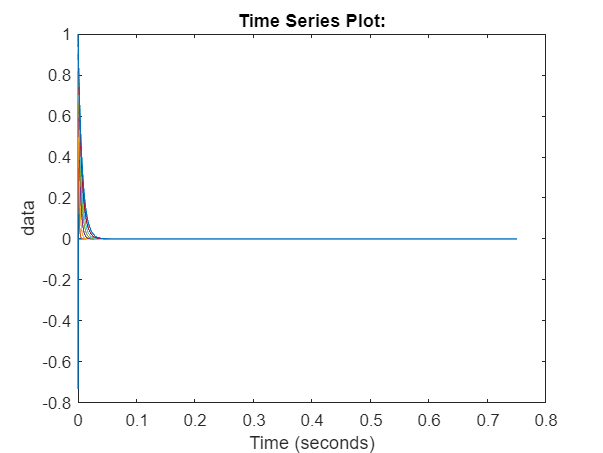

    hold off